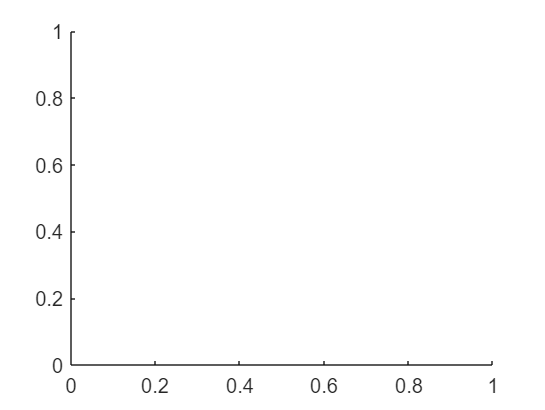

Unrecognized function or variable 'centralPoint'.

Error in short_p>strategy (line 114)
        [minx, miny] = topLeftCoordinate(centralPoint, width, height);

%videoNames =dir("TinyTLP\");
videoNames = {'PolarBear2'};
nFrames = 100;
OverlappingRates = zeros([size(videoNames), nFrames]);
for i=1:size(videoNames)
    name = videoNames{i};
   
    OverlappingRates(i,:) = strategy(name,nFrames);
    kalman(name);
end


%%


function [] = kalman(nom_fitxer)

    close all
    hold off

    path1 = strcat('./ObjectTracker-main/TinyTLP/', nom_fitxer);
    path11 = strcat(path1,'/groundtruth_rect.txt');
    path2 = strcat(path1,'/img/*.jpg');

    BB = importdata(path11);
    Idir = dir(path2);

    figure
    hold on % mantenim sempre oberta la mateixa figura



    filename = horzcat(Idir(1).folder,'/',Idir(1).name);
    I = imread(filename);
    B1 = BB(1,2:5);
    
    im_obje = rgb2gray(imcrop(I,B1));
    im_obj = im_obje(:,:,1);
    imshow(im_obj);


    for i = 1:50
        filename = horzcat(Idir(i).folder,'/',Idir(i).name);
        I2 = imread(filename);

        im_esce = rgb2gray(I2);
        im_esc = im_esce(:,:,1);
        % SIFT
        kp_obj = detectSIFTFeatures(im_obj);
        kp_esc = detectSIFTFeatures(im_esc);

        [feat_obj, kp_obj] = extractFeatures(im_obj,kp_obj);
        [feat_esc, kp_esc] = extractFeatures(im_esc,kp_esc);

        pairs = matchFeatures(feat_obj, feat_esc, 'MatchThreshold',2);

        m_kp_obj = kp_obj(pairs(:,1)); % agafem els millors punts
        m_kp_esc = kp_esc(pairs(:,2));

        % Ransac
        if (m_kp_obj.Count > 3) && (m_kp_esc.Count > 3)
            [T] = estimateGeometricTransform2D(m_kp_obj,m_kp_esc, "affine");
        
            Bi = BB(i,2:5);
            fo = Bi(4);
            co = Bi(3);

            box = [1,1; co,1; co,fo; 1,fo; 1,1];

            nbox = transformPointsForward(T,box);
            imshow(im_esc)
            hold on
            line(nbox(:,1),nbox(:,2));
            drawnow
        end
    end
end





%%

%%
% Versió prova per defecte

% myTracker,  codi inicial del short project

%%
function ORatio = strategy(videoName, nFrames)
    close all
    hold off
    
    path1 = strcat('./TinyTLP/', videoName);
    path11 = strcat(path1,'/groundtruth_rect.txt');
    path2 = strcat(path1,'/img/*.jpg');

    BB = importdata(path11);
    Idir = dir(path2);
    figure
    hold on

    ORatio = zeros(nFrames);

    for i=1:nFrames
        filename = horzcat(Idir(i).folder,'/',Idir(i).name);
        I = imread(filename);

        % Codi Obtenir centre caixa a variable centralPoint(x,y)

        % Càlcul de Bounding Box i tractament de resultat

        width = BB(i,4);
        height = BB(i,5);
        [minx, miny] = topLeftCoordinate(centralPoint, width, height);
        ORatio(i) = bboxOverlapRatio([minx,miny,width,height],BB(i,2:5));
        imshow(I)
        rectangle('Position',[predP(1),predP(3),predW(1),predW(3)],'EdgeColor','red');
        rectangle('Position',BB(i,2:5),'EdgeColor','yellow');
        drawnow
    end
end

function [minx, miny] = topLeftCoordinate(centralPoint, width, height)
    minx = centralPoint(1) - width/2;
    miny = centralPoint(2) - height/2; 
end
%% 
% Comentari: Hue no funciona, hem provat el video Hideway amb el kalman original 
% però canviant el rgb2gray a rgb2hsv ( i agafant la component hue). No funciona 
% ja que es perd molta informació de l'imatge: (comparar captura original, gray 
% i hsv).